Numerical Convolution Examples.

Let v(t) = Av*rect [(t-2)/4] and w(t) = Aw*rect [(t-3)/6]

Find z(t) = v(t) * w(t)

%
clear
clf;
fs = 10; ts = 1/fs; % fs = sampling frequency
t1 = 0; t2 = 15; % Convolution is nonzero from 0 to 10 s; t1-t2 covers this range
Av = 1; Aw = 1;
time = 0:ts:15;
l = length(time);
% Generate v(n) and w(n)
for n = 1:l
    if time(n) <= 4
        v(n) = Av;
    else v(n) = 0;
    end
    if time(n) <= 6
        w(n) = Aw;
    else w(n) = 0;
    end
end

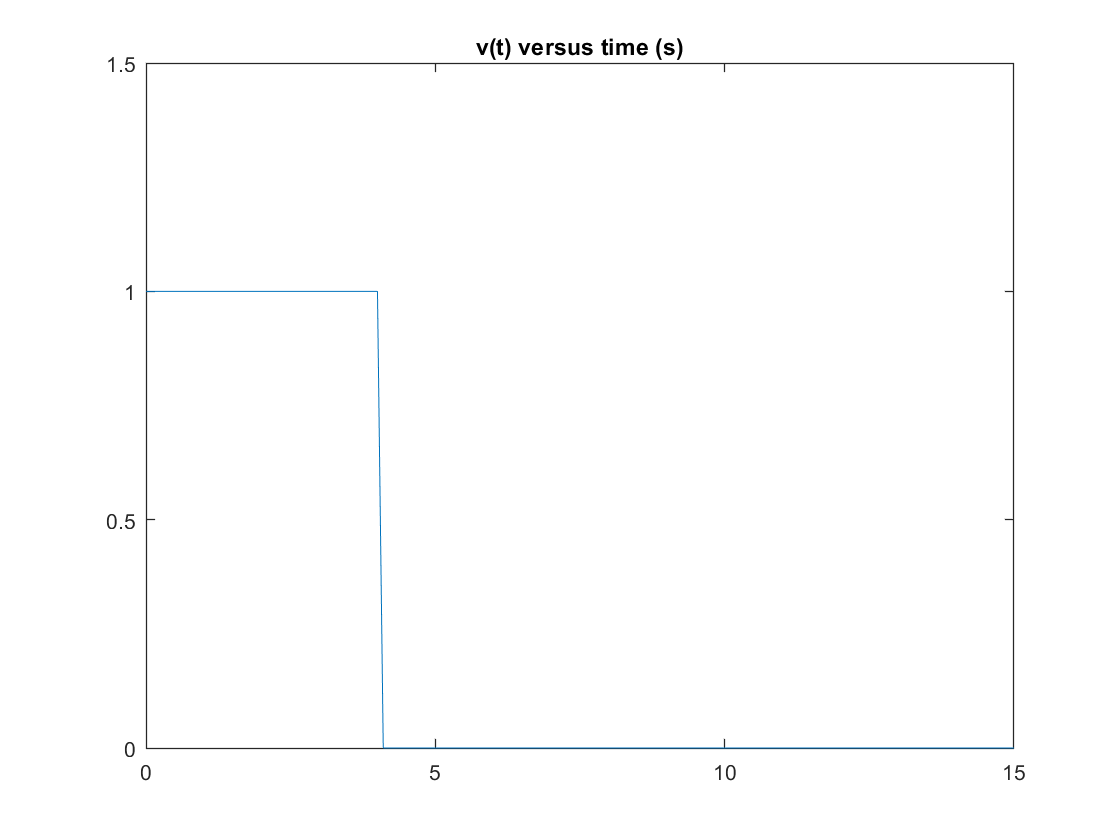

     plot(time,v)
 axis([0 15 0 1.5])
 title('v(t) versus time (s)')

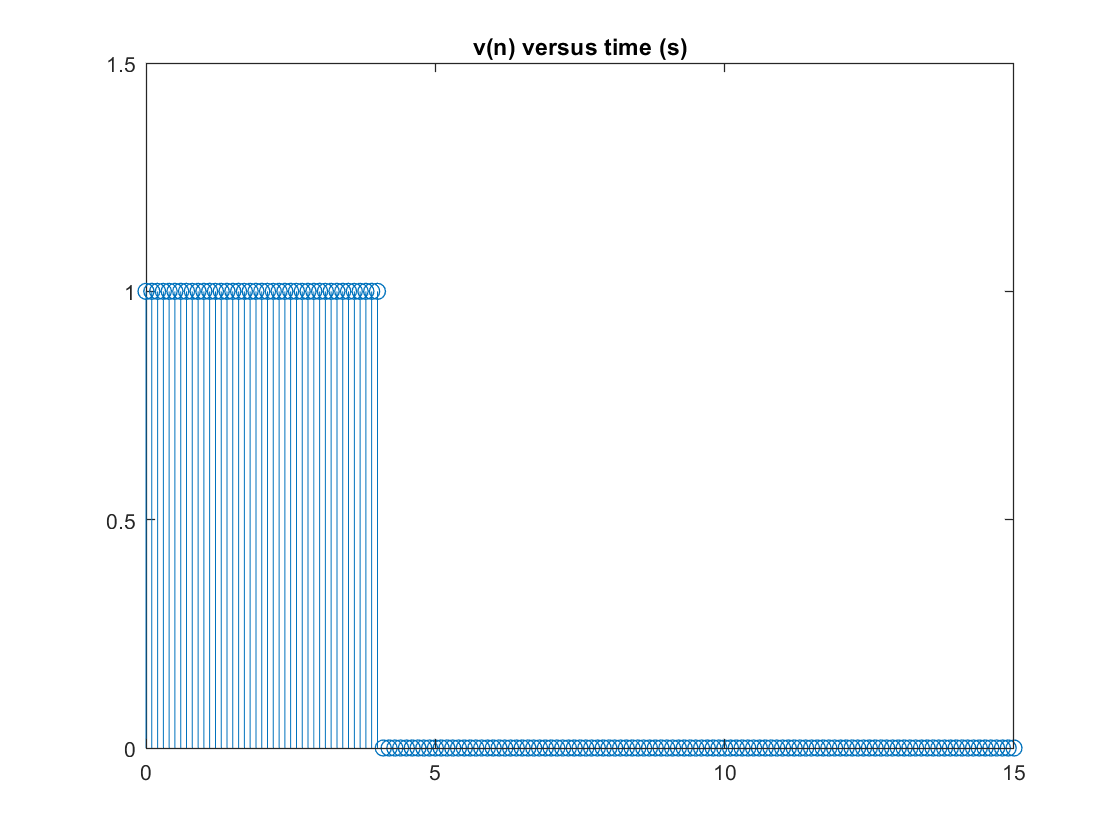

     stem(time,v)
 axis([0 15 0 1.5])
 title('v(n) versus time (s)')

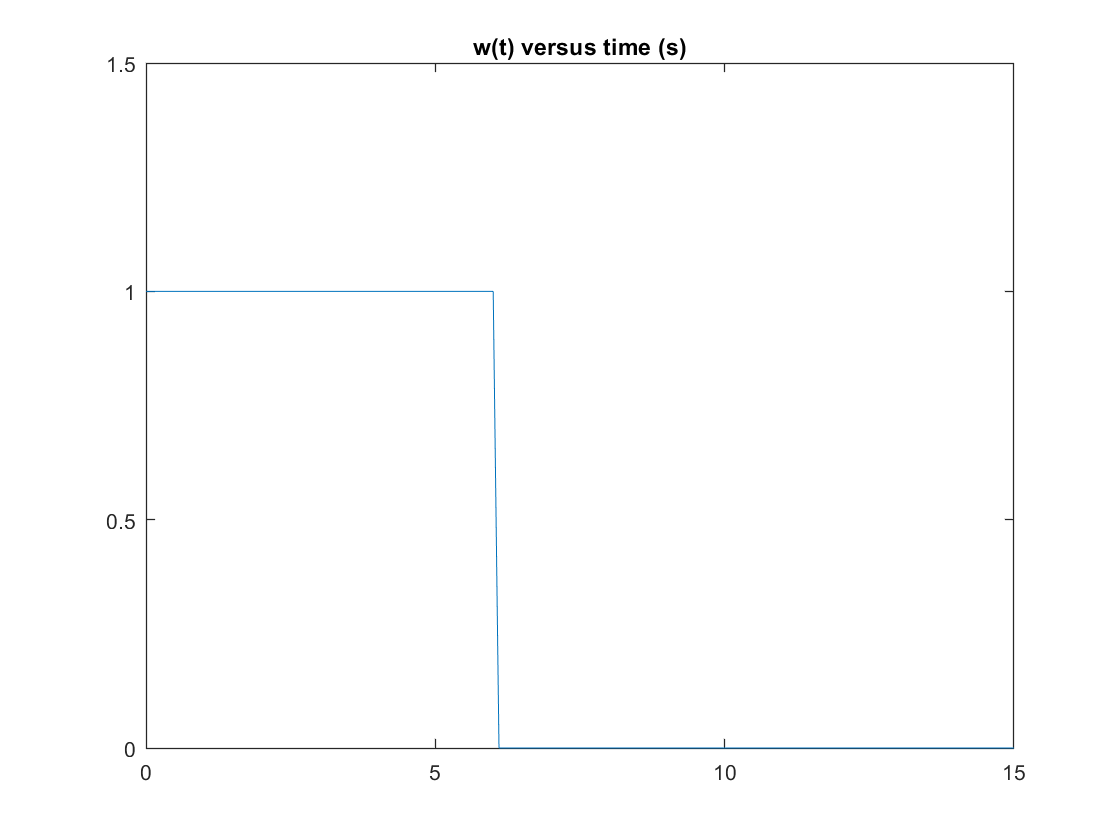

%
plot(time,w)
 axis([0 15 0 1.5])
 title('w(t) versus time (s)')

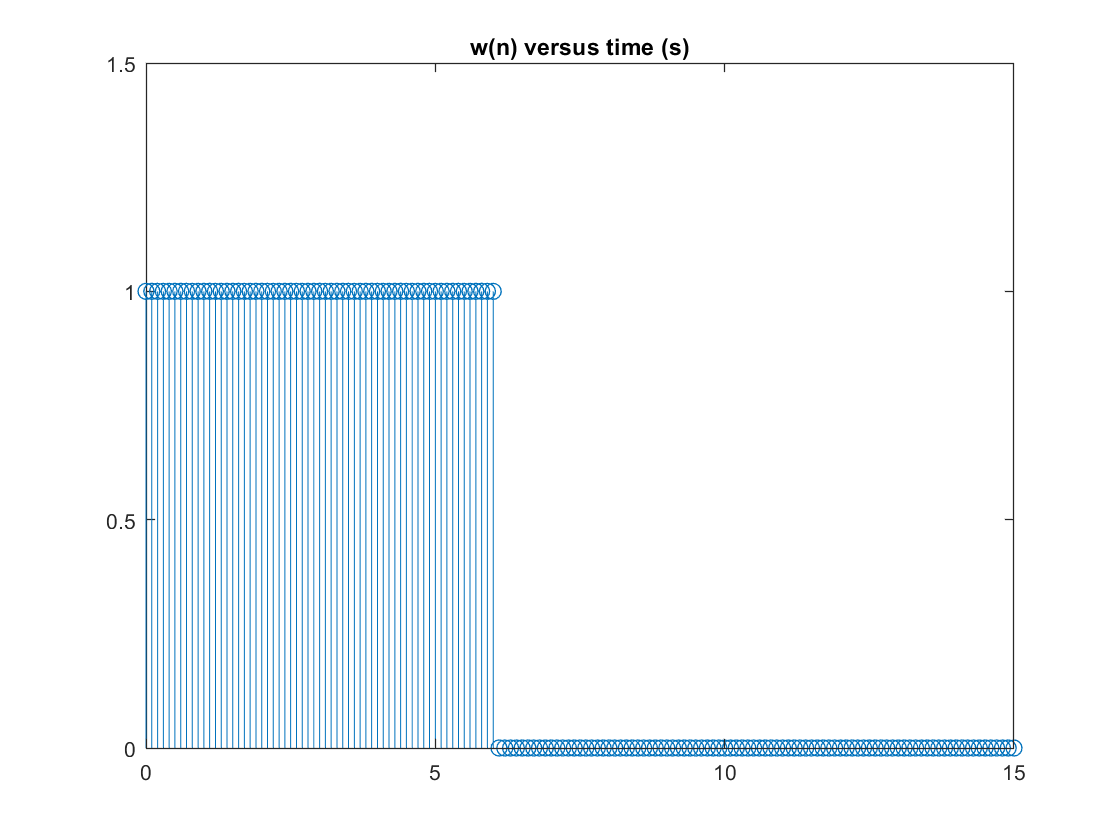

    stem(time,w)
 axis([0 15 0 1.5])
 title('w(n) versus time (s)')

 % Calculate the convolution
 z = ts*conv(v,w);

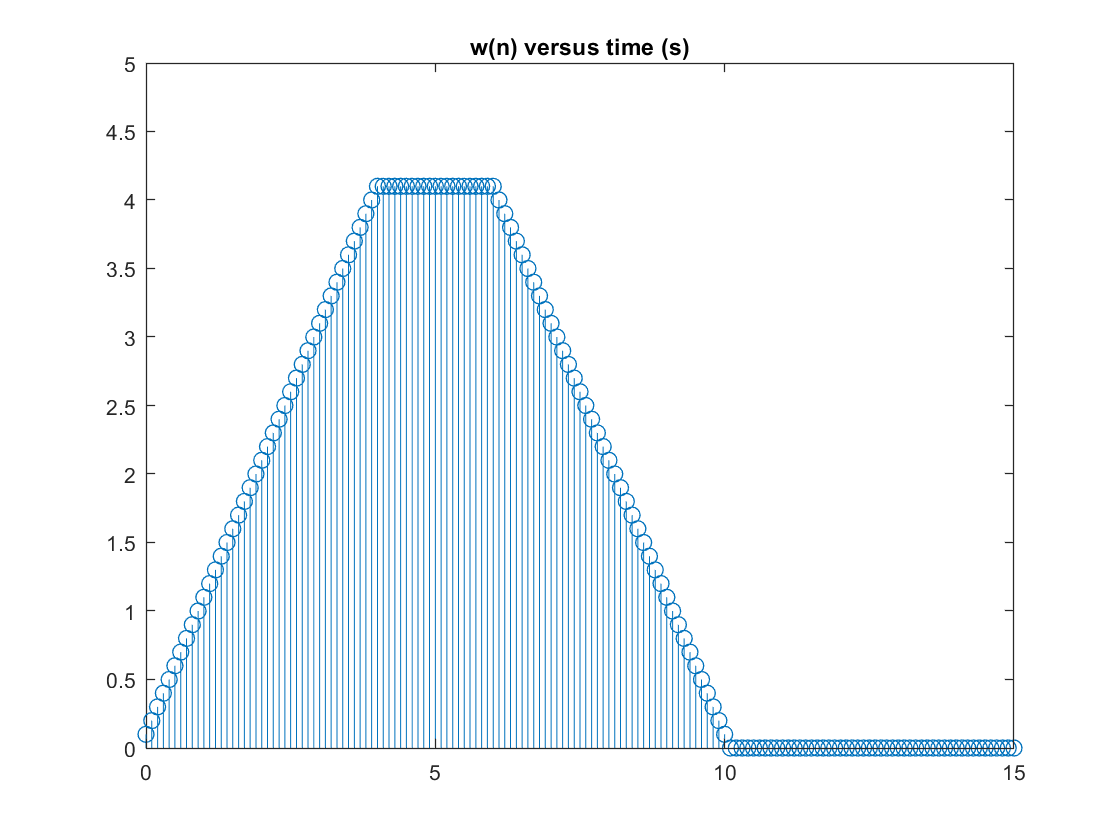

    stem(time,z(1:l))
 axis([0 15 0 5])
 title('w(n) versus time (s)')

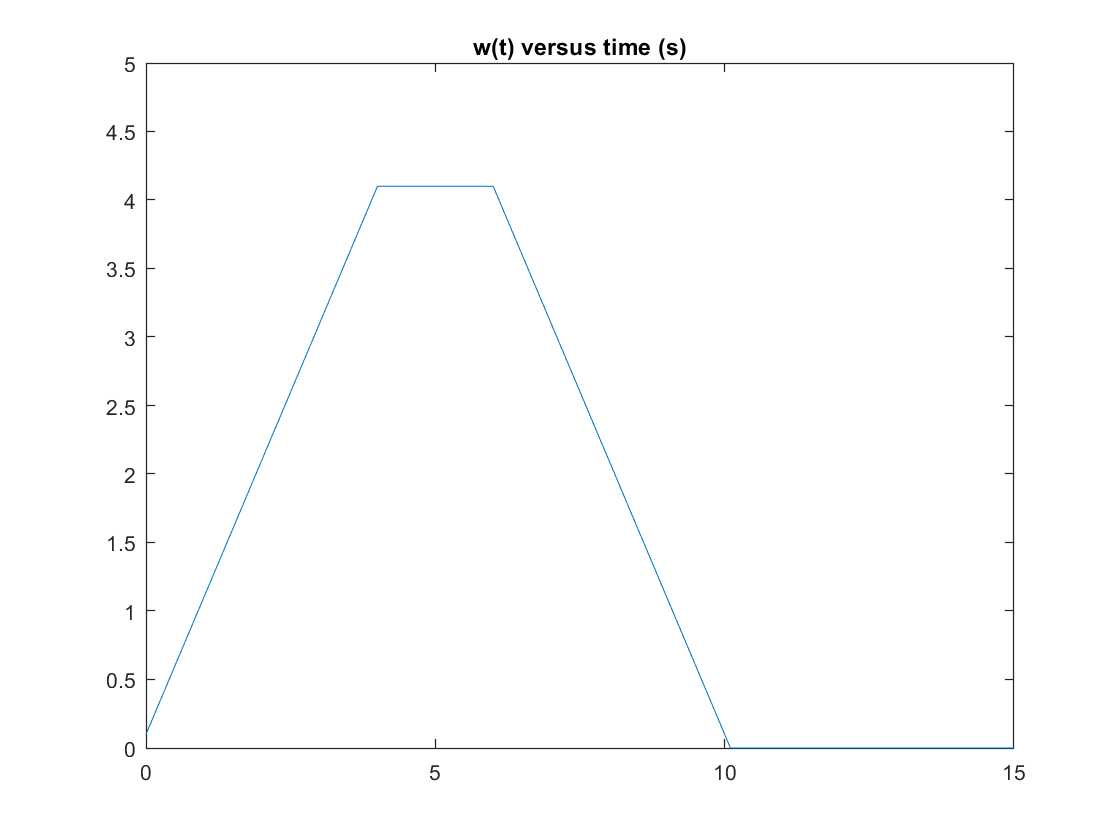

   plot(time,z(1:l))
 axis([0 15 0 5])
   title('w(t) versus time (s)')